
clc; clear; close all;


files = {'caso9.csv', 'caso10.csv', 'caso11.csv', 'caso12.csv'};
legends = {'Case 9', 'Case 10', 'Case 11', 'Case 12'};


line_colors = {[0 0.4470 0.7410], [0.8500 0.3250 0.0980], ...
               [0.4660 0.6740 0.1880], [0.4940 0.1840 0.5560]}; 


ref_L1 = 1.5;      
V_eq = 4.5113;     
t_limit = 800;     

datos = struct();


for i = 1:length(files)
    try
       
        raw = readmatrix(files{i}, 'Delimiter', ';', 'DecimalSeparator', ',');
        
       
        valid_idx = raw(:, 6) > 0.01;
        raw_clean = raw(valid_idx, :);
        
        if isempty(raw_clean), continue; end
        
        
        t_raw = (raw_clean(:,2) - raw_clean(1,2)) / 1000;
        
        t = t_raw;
        u = raw_clean(:, 5);      
        L1_c = raw_clean(:, 6);   
        
        
        mask = (t <= t_limit);
        t = t(mask); u = u(mask); L1_c = L1_c(mask);
        
        
        dt = mean(diff(t));             
        error = abs(ref_L1 - L1_c);     
        IAE = sum(error) * dt;          
        ITAE = sum(t .* error) * dt;    
        
        datos(i).t = t; 
        datos(i).u = u; 
        datos(i).L1_c = L1_c; 
        datos(i).ITAE = ITAE;
        
        fprintf('%s -> IAE: %.2f | ITAE: %.2f\n', legends{i}, IAE, ITAE);
    catch
        fprintf('Error processing file: %s\n', files{i});
    end
end

Case 9 -> IAE: 101.46 | ITAE: 16349.00
Case 10 -> IAE: 101.75 | ITAE: 16372.32
Case 11 -> IAE: 109.03 | ITAE: 19925.12
Case 12 -> IAE: 126.39 | ITAE: 27358.42


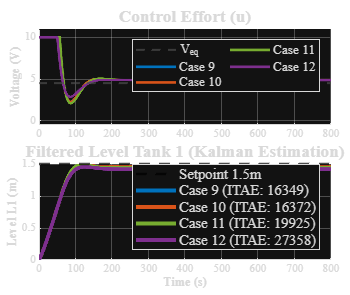



hFig = figure('Color', 'w', 'Position', [100 100 950 800]);
tlo = tiledlayout(2, 1, 'Padding', 'compact', 'TileSpacing', 'tight');


nexttile; hold on;
yline(V_eq, '--', 'Color', [0.3 0.3 0.3], 'LineWidth', 1.5, 'DisplayName', 'V_{eq}');
for i = 1:length(datos)
    if ~isempty(datos(i).t)
        
        plot(datos(i).t, datos(i).u, 'Color', line_colors{i}, 'LineWidth', 2.0, 'DisplayName', legends{i});
    end
end
ylabel('Voltage (V)', 'FontWeight', 'bold'); 
title('Control Effort (u)', 'FontSize', 13);
grid on; xlim([0 t_limit]); ylim([-0.5 11]);
legend('Location', 'northeast', 'NumColumns', 2, 'FontSize', 10);


nexttile; hold on;
yline(ref_L1, 'k--', 'LineWidth', 1.8, 'DisplayName', 'Setpoint 1.5m');
for i = 1:length(datos)
    if ~isempty(datos(i).t)
        
        plot(datos(i).t, datos(i).L1_c, 'Color', line_colors{i}, 'LineWidth', 3.0, ...
            'DisplayName', sprintf('%s (ITAE: %.0f)', legends{i}, datos(i).ITAE));
    end
end
ylabel('Level L1 (m)', 'FontWeight', 'bold'); 
xlabel('Time (s)', 'FontWeight', 'bold');
title('Filtered Level Tank 1 (Kalman Estimation)', 'FontSize', 13);
grid on; xlim([0 t_limit]);
legend('Location', 'southeast', 'FontSize', 11);


set(findall(gcf,'-property','FontName'),'FontName','Times New Roman');